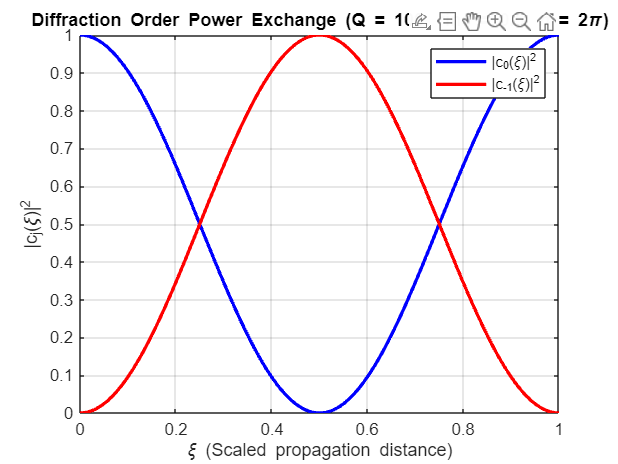

% IV c

% Function Raman-Nath Solver
function raman_nath_solver_c(Q, eta, rinc, jmax, n_sample_points)

    xi_range = linspace(0, 1, n_sample_points);  
    j_vals = -jmax:jmax;                         
    N = length(j_vals);                          
    cj0 = zeros(N, 1);                           
    cj0(jmax + 1) = 1;                           
    
   
    function dcdxi = raman_nath_odes(~, cj)
        dcdxi = zeros(N, 1);  
        
        
        for j_idx = 1:N
            j = j_vals(j_idx);
            
            phase_shift = -(1i * Q / 2) * (rinc + j)^2 * cj(j_idx);
            
            
            coupling = 0;
            if j_idx < N
                coupling = coupling + (1i * eta / 2) * cj(j_idx + 1);  
            end
            if j_idx > 1
                coupling = coupling + (1i * eta / 2) * cj(j_idx - 1);  
            end
            
            
            dcdxi(j_idx) = phase_shift + coupling;
        end
    end

    
    opts = odeset('RelTol', 1e-6, 'AbsTol', 1e-6);  
    [~, cj_vals] = ode45(@raman_nath_odes, xi_range, cj0, opts);
    
    
    cj_final = cj_vals(end, :);
    
% Plotting    
    figure;
    plot(j_vals, abs(cj_final).^2, 'LineWidth', 2);
    xlabel('Diffraction Order (j)');
    ylabel('|c_j(1)|^2');
    title(['Relative Power at Output for \eta = ', num2str(eta), ', Q = 100, r_{inc} = 0.5']);
    grid on;
end

% Input
Q = 100;
rinc = 0.5;
eta = 2 * pi;
xi_range = linspace(0, 1, 50000);  
jmax = 1;  

a0 = 1;  
b0 = 0;  
initial_conditions = [a0; b0];

odefun = @(xi, y) [
    (1i * eta / 2) * y(2);  
    (1i * eta / 2) * y(1)  
];

[~, sol] = ode45(odefun, xi_range, initial_conditions);

a_xi = sol(:, 1);  
b_xi = sol(:, 2);  

c0_squared = abs(a_xi).^2;
c_minus1_squared = abs(b_xi).^2;


% Plotting
figure;
plot(xi_range, c0_squared, 'b', 'LineWidth', 2); hold on;
plot(xi_range, c_minus1_squared, 'r', 'LineWidth', 2);
xlabel('\xi (Scaled propagation distance)');
ylabel('|c_j(\xi)|^2');
legend('|c_0(\xi)|^2', '|c_{-1}(\xi)|^2');
title('Diffraction Order Power Exchange (Q = 100, rinc = 0.5, \eta = 2\pi)');
grid on;